创建带有可自定义文本的嵌套饼状图。

改编自[nested_pie](https://ww2.mathworks.cn/matlabcentral/fileexchange/122167-nested_pie)，功能基本相同，但支持不显示标签和图例

## 语法

## 示例

例1：嵌套饼状图

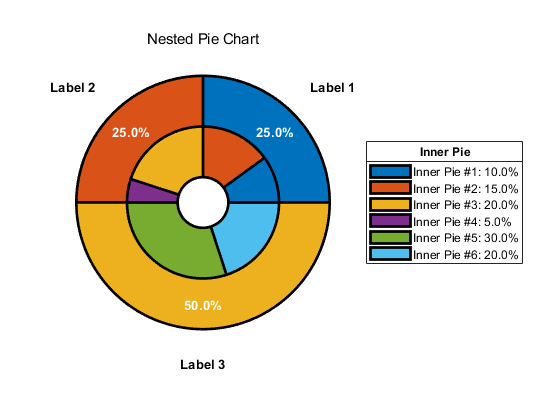

例2：嵌套饼状图，每个楔形带有自定义颜色

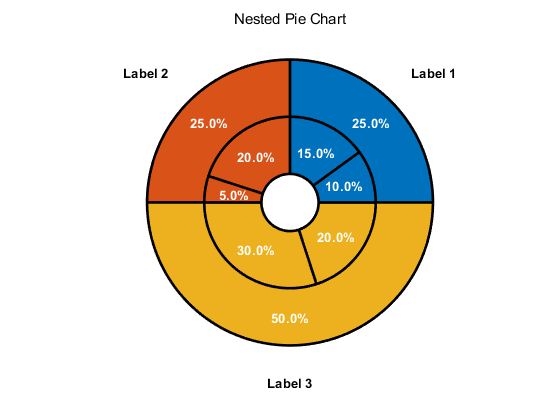

例3：薄饼皮

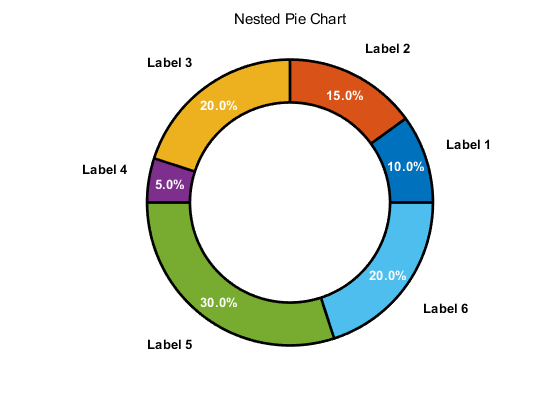

例4：多层嵌套饼状图

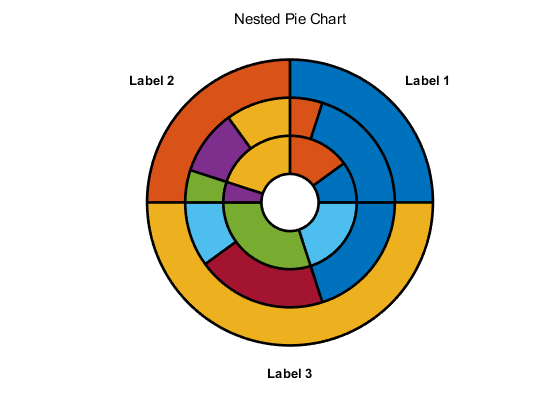

例5：调整图例中饼层显示的顺序

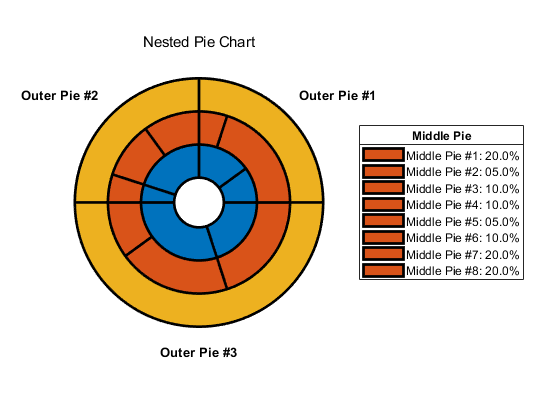

## 输入参数

C cell，用于绘制嵌套饼状图的数据点。它是数值的嵌套元胞数组，从饼图的最内层开始，一直到最外层。

### 名称值参数

RhoLower(1,1)=0.2，用于指定最内层嵌套饼状图的起始半径，范围(0,1)

EdgeColor='k'，用于指定楔形的边缘颜色，参见内置patch的同名参数

LineWidth=2，用于指定楔形的边缘线宽度，参见内置patch的同名参数

LineStyle='-'，用于指定楔形的边缘线样式，参见内置patch的同名参数

WedgeColors(:,1)cell{(:,3)}，RGB三元组的元胞数组，用于指定各个楔形的颜色，默认采用内置 lines colormap。参见内置patch的C参数。

PercentStatus(:,1)matlab.lang.OnOffSwitchState，用于指定每个楔形是否显示百分比文本。默认都是matlab.lang.OnOffSwitchState.on。

PercentPrecision=1，用于指定百分比的文本小数位数。

PercentFontColor='w'，参见内置text的Color参数，用于指定百分比的文本字体颜色。

PercentFontSize=10，参见内置text的FontSize参数，用于指定百分比的文本字体大小。

PercentFontWeight='bold'，参见内置text的FontWeight参数，用于指定百分比的文本字体粗细。

PercentEdgeColor='none'，参见内置text的EdgeColor参数，用于指定百分比的文本框边缘颜色。

PercentBackgroundColor='none'，参见内置text的BackgroundColor参数，用于指定百分比的文本框背景颜色。

LabelText(:,1)string，用于指定每个最外层的标签，默认"Label 标签号"。可以指定为空，表示不显示标签。

LabelFontSize=10，参见内置text的FontSize参数，用于指定标签的字体大小。

LabelFontColor='k'，参见内置text的Color参数，用于指定标签的字体颜色。

LabelFontWeight='bold'，参见内置text的FontWeight参数，用于指定标签的字体粗细。

LabelEdgeColor='none'，参见内置text的EdgeColor参数，用于指定标签的边缘颜色。

LabelBackgroundColor='none'，参见内置text的BackgroundColor参数，用于指定标签的背景颜色。

LabelRotation=0，参见内置text的Rotation参数，用于指定标签的旋转。

LabelOffset=0，用于指定标签的径向偏移量。

LabelInterpreter='none'，参见内置text的Interpreter参数，用于指定标签的解释器。

FillTransparency=1，参见内置patch的FaceAlpha参数，用于指定楔形的填充透明度。

IgnorePercent(1,1)=0，用于忽略低于一定百分比的标签。常用于小百分比，以避免混乱。范围[0,1]。

LegendOrder(:,1)，用于更改饼层在图例中首先显示的顺序，默认从内到外。

## 返回值

h(1,1)matlab.ui.Figure，饼状图的图窗句柄。

**See also** [patch](matlab:doc patch) [lines](matlab:doc lines) [matlab.lang.OnOffSwitchState](matlab:doc matlab.lang.OnOffSwitchState) [text](matlab:doc text)

function fig = NestedPie(C, options)
arguments
	C
	options.rholower = 0.2;
	options.edgecolor = 'k';
	options.linewidth = 2;
	options.linestyle = '-';
	options.wedgecolors
	options.percentstatus
	options.percentprecision = 1;
	options.percentfontcolor = 'w';
	options.percentfontsize = 10;
	options.percentfontweight = 'bold';
	options.percentedgecolor = 'none';
	options.percentbackgroundcolor = 'none';
	options.labeltext string
	options.labelfontsize = 10;
	options.labelfontcolor = 'k';
	options.labelfontweight = 'bold';
	options.labeledgecolor = 'none';
	options.labelbackgroundcolor = 'none';
	options.labelrotation = 0;
	options.labeloffset = 0;
	options.labelinterpreter = 'none';
	options.filltransparency = 1;
	options.axeshandle
	options.ignorepercent = 0;
	options.backgroundcolor = 'w';
	options.legendorder = [];
end

% Pie properties
num_pie = numel(C);
num_outmost = numel(C{end});

% Number of wedges
num_wedges = cellfun(@numel, C);

% Default arguments
HasFields=isfield(options,["wedgecolors","percentstatus","labeltext","axeshandle"]);
if HasFields(1)
	wedge_colors=options.wedgecolors;
else
	wedge_colors=repmat({lines(max(num_wedges(:)))},num_pie,1);
end
if HasFields(2)
	percent_status=options.percentstatus;
else
	percent_status = repmat(matlab.lang.OnOffSwitchState.on,num_pie,1);
end
if HasFields(3)
	label_text=options.labeltext;
else
	label_text=compose("Label %u",1:num_outmost);
end
if HasFields(4)
	ax=options.axeshandle;
	fig=ax.Parent;
else
	fig=figure;
	ax=gca;
end
interval_res = 0.01;

% Axes properties
if isprop(fig, "Color")
    fig.Color = options.backgroundcolor;
end
ax.Color = options.backgroundcolor;

% Axis properties
hold(ax, 'on');
axis(ax, 'square');
axis(ax, [-1, 1, -1, 1] * 1.2);

% Axis properties
ax.XTickLabel = [];
ax.YTickLabel = [];
ax.XColor = 'none';
ax.YColor = 'none';

% Error checking
if options.rholower < 0 || options.rholower > 1
    error('Error: The starting radius must be a value between [0, 1].');
end

HasLabels=~isempty(label_text);
if HasLabels&&numel(label_text) ~= num_outmost
    error('Error: The label text must equal the length of the wedges in the outer most layer.');
end

% Initialize rho
rho_upper = 1;
rho_range = rho_upper - options.rholower;
rho_interval = rho_range/num_pie;
rho = options.rholower:rho_interval:rho_upper;
tol = eps(10);

% Iterate through number of nested pies
for ii = 1:num_pie
    % Initialize
    sub_pie = C{ii}; % Convert from cell to numerical array
    num_wedge = num_wedges(ii);
    wedge_color = wedge_colors{ii};
    bEssentiallyEqual = false;

    % Compare taking into account floating-point number
    if abs(1 - sum(sub_pie)) <= tol
        bEssentiallyEqual = true;
    end

    % Check if data does not sum to one
    if ~bEssentiallyEqual
        % Display warning
        warning('Data does not sum to 1. Attempting to normalize data...');

        % Normalize data to add up to one
        sub_pie = sub_pie / sum(sub_pie);
    end

    % Initialize theta
    theta = 2 * pi * sub_pie;
    theta = cumsum(theta);
    theta = [0, theta]; %#ok<*AGROW>

    % Iterate through number of wedges
    for jj = 1:num_wedge
        % Initialize
        theta_start = theta(jj);
        theta_end = theta(jj+1);

        rho_start = rho(ii);
        rho_end = rho(ii+1);

        % Make cyclic
        theta_sides = [theta_start, theta_end, theta_end, theta_start, theta_start];
        rho_sides = [rho_start, rho_start, rho_end, rho_end, rho_start];

        % Initialize
        x_patch = [];
        y_patch = [];

        % Iterate through a four-sided polygon
        for kk = 1:4
            % Initialize
            interval = interval_res;

            % Check if interval needs to be flipped
            if theta_sides(kk) > theta_sides(kk+1)
                interval = -interval_res;
            end

            % Polar coordinates of polygon
            theta_side = theta_sides(kk):interval:theta_sides(kk+1);
            rho_side = rho_sides(kk) * ones(1, length(theta_side));

            % Convert from polar to cartesian coordinates
            [x_cart, y_cart] = pol2cart(theta_side, rho_side);

            % Append to array
            x_patch = [x_patch, x_cart];
            y_patch = [y_patch, y_cart];
        end

        % Create patch object
        p = patch(ax, x_patch, y_patch, wedge_color(jj, :),...
            'LineStyle', options.linestyle,...
            'EdgeColor', options.edgecolor,...
            'LineWidth', options.linewidth,...
            'FaceAlpha', options.filltransparency);
        p.Tag = sprintf('Layer %i, Wedge %i', ii, jj);
    end

    % Find midpoint of theta and rho
    theta_diff = diff(theta)/2;
    theta_diff = theta(1:end-1) + theta_diff;

    rho_wedge = rho(ii:ii+1);
    rho_delta = diff(rho_wedge)/2;
    rho_diff = rho_wedge(1:end-1) + rho_delta;
    rho_labels = rho_wedge(end) + rho_delta;

    % Iterate through rho midpoints
    for jj = 1:length(rho_diff)
        % Initialize
        rho_txt = rho_diff(jj);
        rho_label = rho_labels(jj);

        % Iterate through theta midpoints
        for kk = 1:length(theta_diff)
            % Initialize
            theta_txt = theta_diff(kk);
            sub_percent = sub_pie(kk)*100;

            % Check if display percent status
			if percent_status(ii)==matlab.lang.OnOffSwitchState.on
				% Check if non-trivial amount
				if sub_percent > options.ignorepercent
					% Format percentage text
					precision_txt = sprintf('%i', options.percentprecision);
					percent_txt = sprintf(['%.', precision_txt, 'f%%'], sub_percent);

					% Convert from polar to cartesian
					[x_txt, y_txt] = pol2cart(theta_txt, rho_txt);

					% Display percentage text
					text(x_txt, y_txt, percent_txt,...
						'Color', options.percentfontcolor,...
						'FontWeight', options.percentfontweight,...
						'FontSize', options.percentfontsize,...
						'EdgeColor', options.percentedgecolor,...
						'BackgroundColor', options.percentbackgroundcolor,...
						'HorizontalAlignment', 'center');
				end
			end
        end
    end
end

% Only for outermost
% Check if non-trivial amount
if sub_percent > options.ignorepercent&&HasLabels
	% Convert from polar to cartesian
	[x_label, y_label] = pol2cart(theta_txt, rho_label+options.labeloffset);

	[horz_align, vert_align] = quadrant_position(theta_txt);

	% Display pie labels
	text(ax, x_label, y_label, label_text(kk),...
		'Color', options.labelfontcolor,...
		'FontWeight', options.labelfontweight,...
		'FontSize', options.labelfontsize,...
		'EdgeColor', options.labeledgecolor,...
		'BackgroundColor', options.labelbackgroundcolor,...
		'Rotation', options.labelrotation,...
		'HorizontalAlignment', horz_align,...
		'VerticalAlignment', vert_align,...
		'Interpreter', options.labelinterpreter);
end

% Check if legend order is valid
if ~isempty(options.legendorder) &&...
        isnumeric(options.legendorder) &&...
        length(options.legendorder) == num_pie &&...
        length(unique(options.legendorder)) == num_pie &&...
        max(options.legendorder) == num_pie

    % Get axes handle
    f = fig;
    h = f.Children;
    a = findobj(h, 'Type', 'axes');

    % Iterate in backwards order
    for ii = length(options.legendorder):-1:1
        % Initialize
        order = options.legendorder(ii);

        % Compose layer number
        tag_str = compose("Layer %i", order);

        % Patch handles
        p = a.Children;

        % Find relevant pie layer
        h = findobj(p, '-regexp', 'Tag', tag_str);

        % Stack from bottom
        uistack(h, "bottom");
    end
elseif ~isempty(options.legendorder)
    error('Error: Please enter in valid number of pie layers to rearrange legend order.');
end

    function [horz_align, vert_align] = quadrant_position(theta_point)
        % Find out which quadrant the point is in
        if theta_point == 0
            quadrant = 0;
        elseif theta_point == pi/2
            quadrant = 1.5;
        elseif theta_point == pi
            quadrant = 2.5;
        elseif theta_point == 3*pi/2
            quadrant = 3.5;
        elseif theta_point == 2*pi
            quadrant = 0;
        elseif theta_point > 0 && theta_point < pi/2
            quadrant = 1;
        elseif theta_point > pi/2 && theta_point < pi
            quadrant = 2;
        elseif theta_point > pi && theta_point < 3*pi/2
            quadrant = 3;
        elseif theta_point > 3*pi/2 && theta_point < 2*pi
            quadrant = 4;
        end

        % Adjust label alignment depending on quadrant
        switch quadrant
            case 0
                horz_align = 'left';
                vert_align = 'middle';
            case 1
                horz_align = 'left';
                vert_align = 'bottom';
            case 1.5
                horz_align = 'center';
                vert_align = 'bottom';
            case 2
                horz_align = 'right';
                vert_align = 'bottom';
            case 2.5
                horz_align = 'right';
                vert_align = 'middle';
            case 3
                horz_align = 'right';
                vert_align = 'top';
            case 3.5
                horz_align = 'center';
                vert_align = 'top';
            case 4
                horz_align = 'left';
                vert_align = 'top';
        end
    end

end